# Plots

clear all;
global x1; global x2; global x3;global x4;
global a1;global a2;global a3;
x1 = 1;
x2 = 1;
x3 = 1;
x4 = 1;

a1 = 1;
a2 = -1;
a3 = 1;

global N; global sig;
N = 5:20;
sig = 0.04

sig = 0.0400

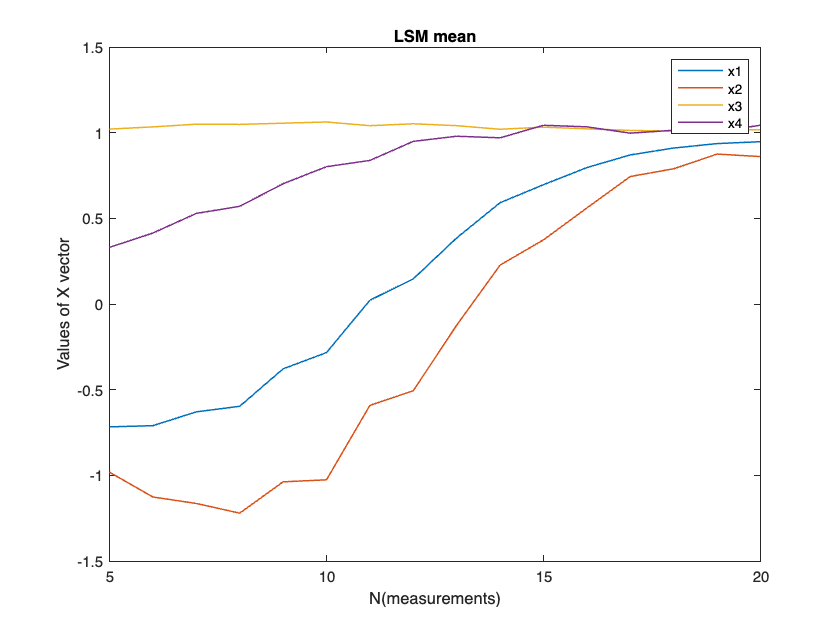


dhdx=@dhdxdef;
% calman H
ht=@htdef;
angle=@angledef;
calmanmy=@calmandef;
dispValuesCalman=zeros(4,max(N)-min(N));
dispValuesLSM=zeros(4,max(N)-min(N));
meanValuesCalman=zeros(4,max(N)-min(N));
meanValuesLSM=zeros(4,max(N)-min(N));
niter=100; % number of experiments for avg values

for n = 1 : length(N)
    xlsqr = zeros(niter, 4);
    xcalman = zeros(niter, 4);

    for k = 1:niter
        %     random noise with dispersion=sig
        da = sig*randn([N(n) 1]) ;
        A = zeros(N(n), 4);
        b = zeros(N(n),1);

        for l = 1:N(n)
            t = l/10;
            %         take noise(l) but take angle(l/10)
            mult = (sin(angle(t)+ da(l)))^2/t;
            A(l,1) = t;
            A(l,2) = -t*cot(angle(t)+ da(l));
            A(l,3) = 1;
            A(l,4) = -cot(angle(t)+ da(l));
            A(l,:)=mult*A(l,:);

            b(l) = (a1*t^2+a2*t+a3)*mult;

        end
        %     calc vector X by last squares method
        xlsqr(k,:) = A\b;
        %     calc vector X by calman filter
        xcalman(k,:) = calmanmy(da,n);
    end
    meanValuesLSM(:,n)= mean(xlsqr,1)';
    meanValuesCalman(:,n)= mean(xcalman,1)';

    dispValuesLSM(:,n)=diag(cov(xlsqr))';
    dispValuesCalman(:,n)=diag(cov(xcalman))';
end

plot(N,meanValuesLSM,LineWidth=1);xlim([min(N) max(N)]);ylim([-1.5 1.5]);
xlabel("N(measurements)"); ylabel("Values of X vector");
legend('x1','x2','x3','x4');title("LSM mean");

hold on;
hold off;

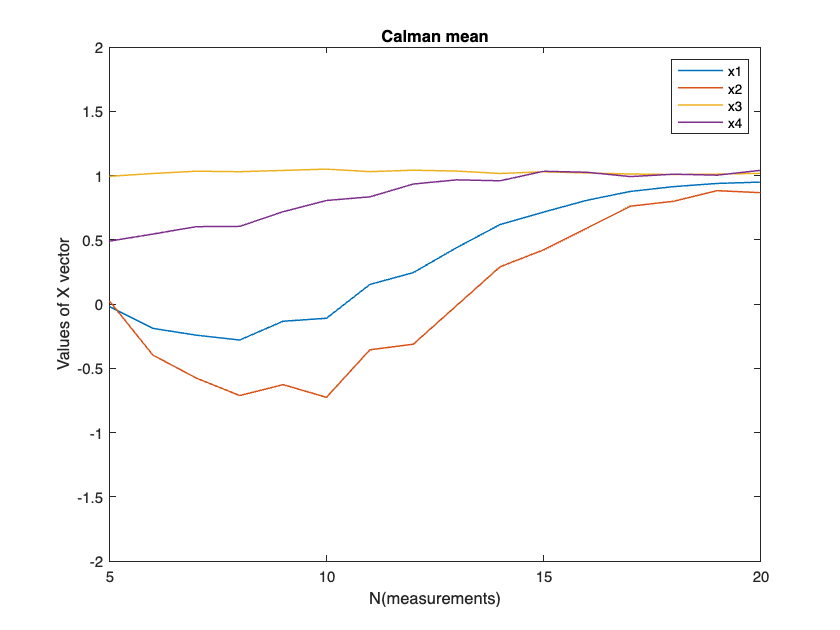


plot(N,meanValuesCalman,LineWidth=1);xlim([min(N) max(N)]);ylim([-2 2]);
xlabel("N(measurements)"); ylabel("Values of X vector");
legend('x1','x2','x3','x4');title("Calman mean");

hold on;
hold off;

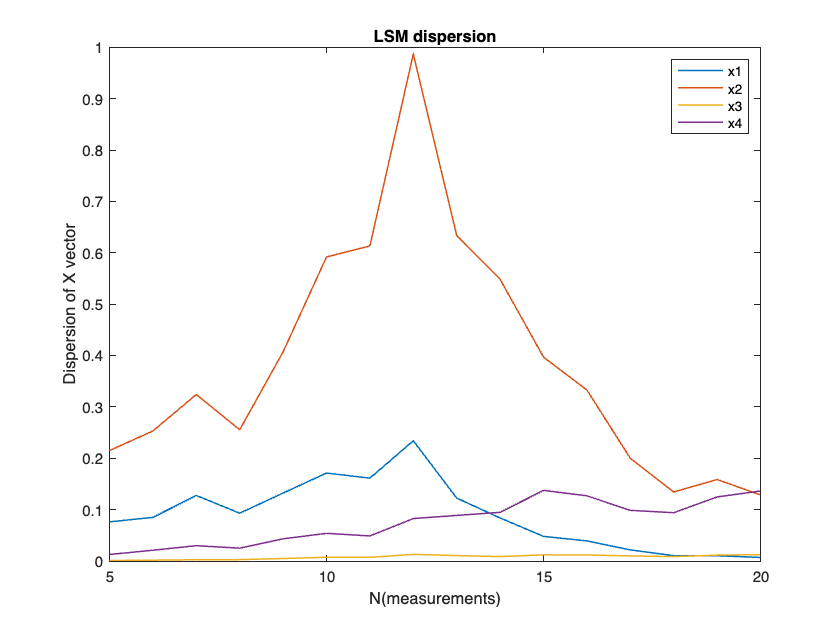


plot(N,dispValuesLSM,LineWidth=1);xlim([min(N) max(N)]);ylim([0 1]);
xlabel("N(measurements)"); ylabel("Dispersion of X vector");
legend('x1','x2','x3','x4');title("LSM dispersion");

hold on;
hold off;

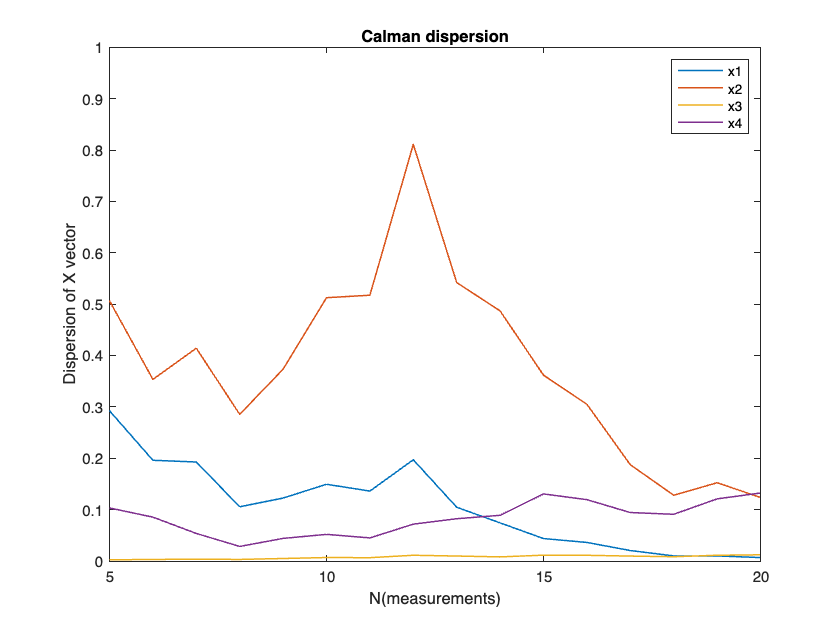


plot(N,dispValuesCalman,LineWidth=1);xlim([min(N) max(N)]);ylim([0 1]);
xlabel("N(measurements)"); ylabel("Dispersion of X vector");
legend('x1','x2','x3','x4');title("Calman dispersion");
hold on;

function ret = dhdxdef (t, k)
    global x1; global x2; global x3;global x4;
    global a1;global a2;global a3;
    
    fractiondef=(x1*t+x3-a1*t^2-a2*t-a3)/(x2*t+x4);
    
    koef=-1/(1+fractiondef^2)/(x2*t+x4);
    
    dhdx = koef*[t -t*fractiondef 1 -fractiondef];
    
    ret=dhdx(k);
end

% retrurn angle
function ret = angledef (t)
    global x1; global x2; global x3;global x4;
    global a1;global a2;global a3; 
%     acot2(x,y)=atan2(y,x)
    ret = atan2(x2*t+x4,x1*t+x3-a1*t*t-a2*t-a3);
end

% retrun h
function ret = htdef (t, da)
    mult = (sin(angledef(t)+ da))^2/t;
    ret=mult*[t -t*cot(angledef(t)+ da) 1 -cot(angledef(t)+ da)];
end

% return X value after N iteration
function X0 = calmandef (da,n)
global sig; global N; global a1;global a2;global a3;

X0 = [1.5;1.5;1.5;1.5];
Pxx = eye(4);
for k = 1:N(n)
    t = k/10;
    h = htdef(t, da(k));
    mult=(sin(angledef(t)+ da(k)))^2/t;
    z = (a1*t^2+a2*t+a3)*mult;
    X0 = X0 + (Pxx*h')/(h*Pxx*h'+ sig^2)*(z-h*X0);
    Pxx = Pxx - (Pxx*h')/(h*Pxx*h'+ sig^2)*h*Pxx;
end
end